## Position Control using PID Controller

%   Initial clearing of the screen and the memory
clear
clc

**Data for links and PID**

m1 = 16.726;
m2 = 6.237;
m3 = 12.243;
l1 = 0.23;
l2 = 0.43;
l3 = 0.19;
w1 = 0.069;
w2 = 0.129;
w3 = 0.057;
kp = 700; ki = 100; kd = 250; % PID controller coeffitients 
StopTime = 20;
AB = [l1 w1 w1]; % m dimensions of the first link
BC = [w2 w2 l2];
CD = [w3 w3 l3];

**Run models**

addpath(genpath('mr')); % we use function library by Kevin Lynch
PPR_simscapePID % it opens the model 

outSim = sim('PPR_simscapePID'); % it runs it 

**Plot of desired and actual positions**

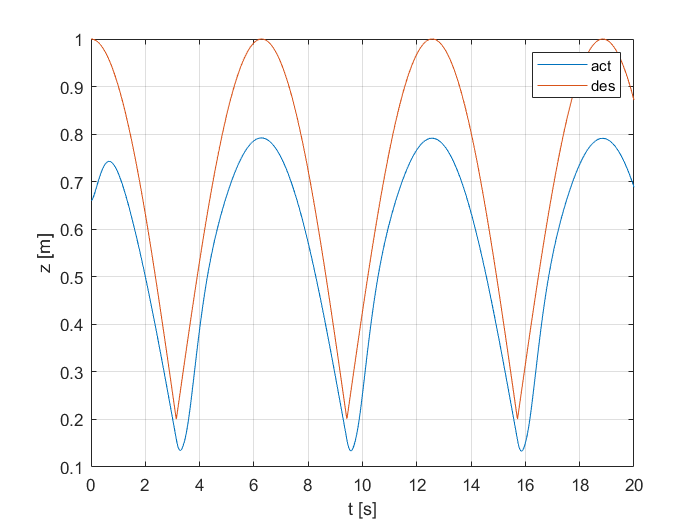

figure;
title('Trajectory');
plot(outSim.outputs.p_act.time, outSim.outputs.p_act.data(:,3),...
	 outSim.outputs.p_des.time, outSim.outputs.p_des.data(:,3));
grid on;
legend('act', 'des');
xlabel('t [s]');
ylabel('z [m]');

**Plot of desired and actual positions in the x direction**

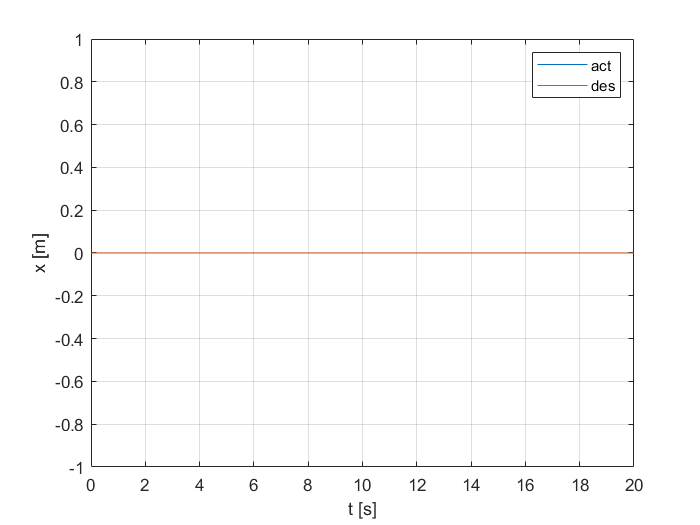

figure;
title('Trajectory');
plot(outSim.outputs.p_act.time, outSim.outputs.p_act.data(:,1),...
	 outSim.outputs.p_des.time, outSim.outputs.p_des.data(:,1));
grid on;
legend('act', 'des');
xlabel('t [s]');
ylabel('x [m]');

**Plot of desired and actual positions in the y direction**

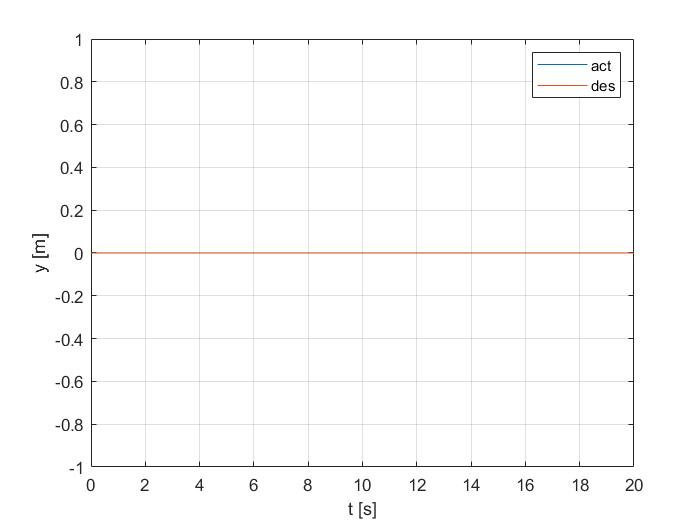

figure;
title('Trajectory');
plot(outSim.outputs.p_act.time, outSim.outputs.p_act.data(:,2),...
	 outSim.outputs.p_des.time, outSim.outputs.p_des.data(:,2));
grid on;
legend('act', 'des');
xlabel('t [s]');
ylabel('y [m]');

#### Plots Torques and Forces

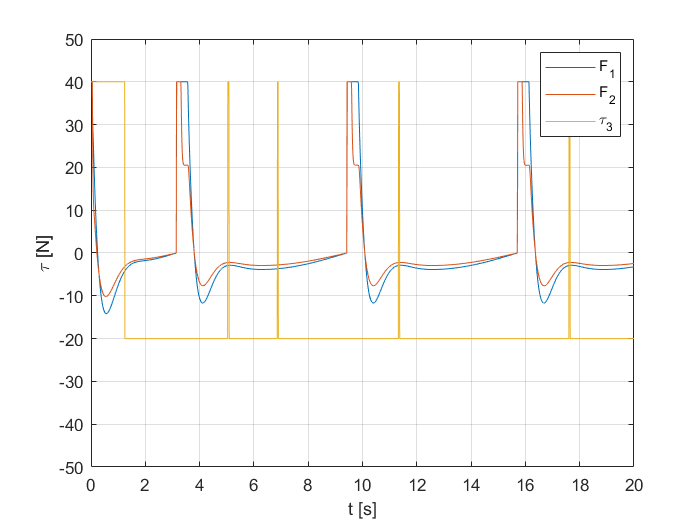

figure;
title('Joints state');
plot(outSim.outputs.tau.time, outSim.outputs.tau.data(:,1),...
	 outSim.outputs.tau.time, outSim.outputs.tau.data(:,2),...
     outSim.outputs.tau.time, outSim.outputs.tau.data(:,3));
grid on;
legend('F_1', 'F_2','\tau_3');
xlabel('t [s]');
ylabel('\tau [N]');
ylim([-50 50]);